# ความน่าจะเป็นและสัญญาณสุ่ม (Probability & Random Signal)

# ตอนที่ 6 : ความสัมพันธ์ระหว่างตัวแปรสุ่มหลายตัว (Relationship between Multiple Random Variables)

## ค่าแปรปรวนร่วมเกี่ยว (Covariance)

**ค่าของตัวแปรสุ่มสองตัวสามารถแปรปรวนร่วมกันได้ เราเรียกค่านี้ว่าค่าแปรปรวนร่วมเกี่ยว (covariance) **

หากเรากำหนดให้ $X$ และ $Y$ เป็นตัวแปรสุ่ม ค่าแปรปรวนร่วมเกี่ยว $\mathrm{Cov}\left\lbrace X,Y\right\rbrace$ หรือ $\sigma_{XY}$ ของตัวแปร $X$ และ $Y$ จะถูกนิยามดังต่อไปนี้


$$\begin{array}{l}
\sigma_{XY} =\mathrm{Cov}\left\lbrace X,Y\right\rbrace =\mathrm{E}\left\lbrace \left(X-\mu_X \right)\cdot \left(Y-\mu_Y \right)\right\rbrace \\
=\mathrm{E}\left\lbrace X\cdot Y-\mu_X \cdot Y-X\cdot \mu_Y +\mu_X \cdot \mu_Y \right\rbrace \\
=\mathrm{E}\left\lbrace X\cdot Y\right\rbrace -\mu_X \cdot \mathrm{E}\left\lbrace Y\right\rbrace -\mu_Y \cdot E\left\lbrace X\right\rbrace +\mu_X \cdot \mu_Y \\
=\mathrm{E}\left\lbrace X\cdot Y\right\rbrace -\mu_X \cdot \mu_Y 
\end{array}$$


ซึ่งความแปรปรวนร่วมเกี่ยวจะมีสมบัติดังต่อไปนี้


$$\begin{array}{l}
\mathrm{Cov}\left\lbrace X,Y\right\rbrace =\mathrm{Cov}\left\lbrace Y,X\right\rbrace \\
\left|\mathrm{Cov}\left\lbrace X,Y\right\rbrace \right|\le \sqrt{\mathrm{Var}\left\lbrace X\right\rbrace \cdot \mathrm{Var}\left\lbrace Y\right\rbrace }
\end{array}$$


ค่าแปรปรวนร่วมเกี่ยวนั้นอธิบายถึงความแปรปรวนที่สองตัวแปรนั้นแปรเปลี่ยนไปในทางเดียวกัน

## ค่าสหสัมพันธ์ (Correlation)

**อีกหนึ่งค่าที่สามารถอธิบายความสัมพันธ์ระหว่างตัวแปรสุ่มสองตัวได้คือค่าสหสัมพันธ์ (correlation) **

หากเรากำหนดให้ $X$ และ $Y$ เป็นตัวแปรสุ่ม ค่าสหสัมพันธ์ของตัวแปรสุ่มทั้งสอง $\rho_{XY}$ หรือ $\mathrm{Cor}\left\lbrace X,Y\right\rbrace$จะถูกนิยามดังต่อไปนี้


$$\begin{array}{l}
\rho_{XY} =\mathrm{Cor}\left\lbrace X,Y\right\rbrace =\frac{\sigma_{XY} }{\sigma_X \cdot \sigma_Y }\\
-1\le \mathrm{Cor}\left\lbrace X,Y\right\rbrace \le 1
\end{array}$$


หากเรามีชุดข้อมูลเป็นคู่อันดับ $\left\langle x,y\right\rangle$ เราสามารถใช้ฟังก์ชัน corrcoef เพื่อคำนวณหาค่าสหสัมพันธ์ระหว่างข้อมูลชุด x และข้อมูลชุด y ซึ่งจะได้ผลลัพธืเป็นเมตริกซ์ดังต่อไปนี้


$$\mathrm{corrcoef}\left(X,Y\right)=\left\lbrack \begin{array}{cc}
\mathrm{Cor}\left\lbrace X,X\right\rbrace  & \mathrm{Cor}\left\lbrace X,Y\right\rbrace \\
\mathrm{Cor}\left\lbrace X,Y\right\rbrace  & \mathrm{Cor}\left\lbrace Y,Y\right\rbrace 
\end{array}\right\rbrack$$


ซึ่ง $\mathrm{Cor}\left\lbrace X,X\right\rbrace =\mathrm{Cor}\left\lbrace Y,Y\right\rbrace =1$

เราจะใช้สมาชิกตัวที่ไม่ได้อยู่ในแนวทแยงเท่านั้นเนื่องจากค่าสหพันธ์ของค่าเดียวกันจะมีผลเป็น 0 เสมอ

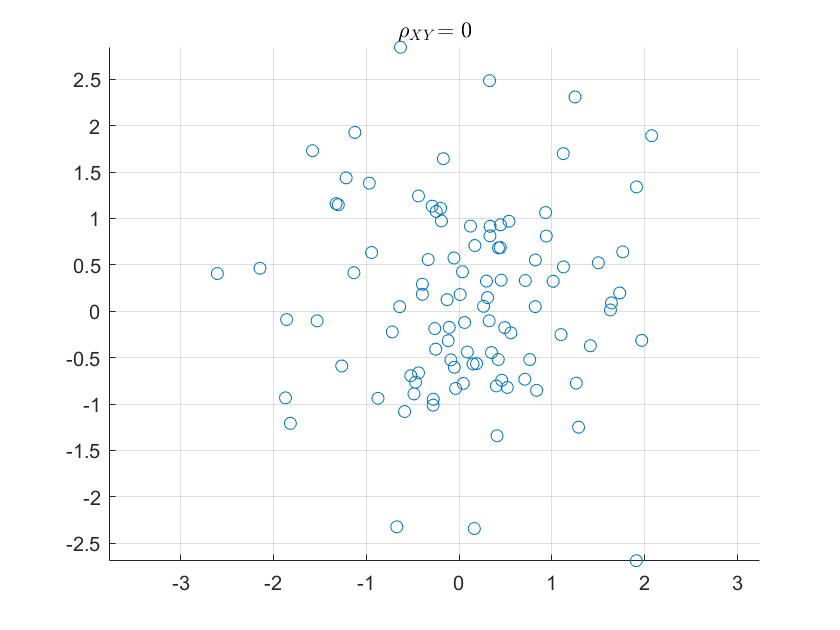

x = randn(1,100);
y = randn(1,100);
clf
ax = axes;
hold(ax,'on')
grid(ax,'on')
plot(ax,x,y,'o')
axis(ax,'equal')
title(ax,'$\rho_{XY}$= 0','Interpreter',"latex")

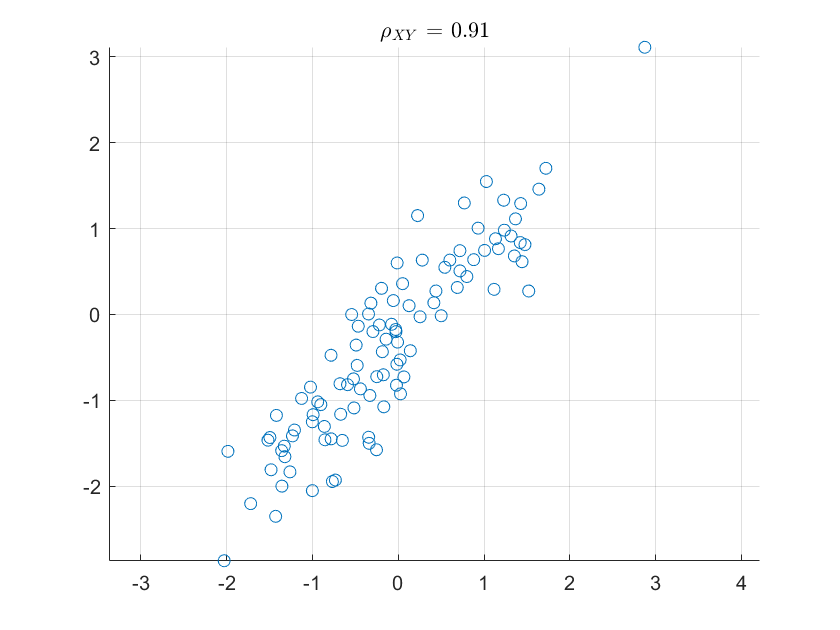


x = randn(1,100);
y = x+0.5*(randn(size(x))-0.5);
clf
ax = axes;
hold(ax,'on')
grid(ax,'on')
plot(ax,x,y,'o')
axis(ax,'equal')
C = corrcoef(x,y);
title(ax,sprintf('$\\rho_{XY}$ = %.3f',C(1,2)),'Interpreter',"latex")

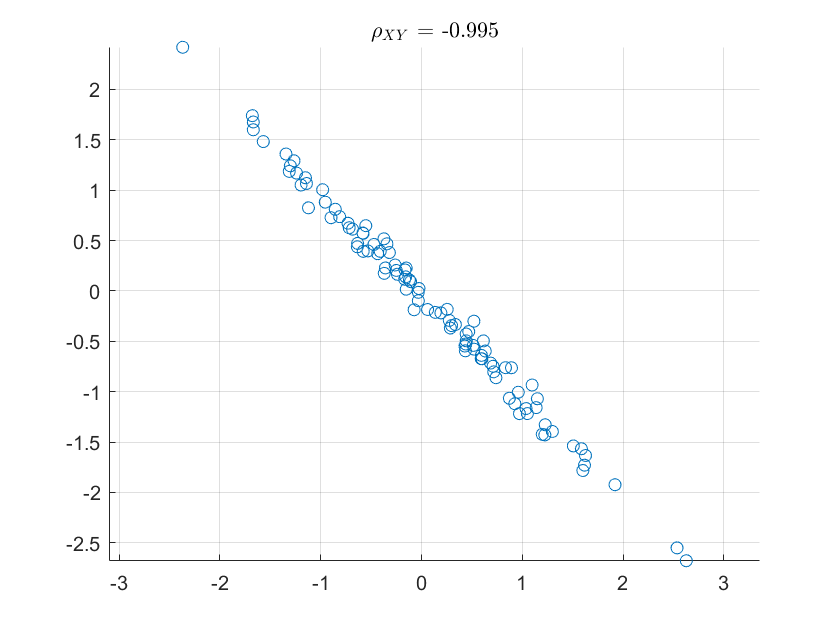


x = randn(1,100);
y = -x+0.1*(randn(size(x))-0.5);
clf
ax = axes;
hold(ax,'on')
grid(ax,'on')
plot(ax,x,y,'o')
axis(ax,'equal')
C = corrcoef(x,y);
title(ax,sprintf('$\\rho_{XY}$ = %.3f',C(1,2)),'Interpreter',"latex")

## สมบัติของค่าคาดหวังและค่าแปรปรวน (Properties of Expected Value & Variance)

ในกรณีที่เรามีค่าที่ไม่แน่นอนมากกว่าหนึ่งค่ามาผสมรวมกัน เราจะได้ค่าที่มีความไม่แน่นอนใหม่ ทั้งค่าคาดหวังและค่าแปรปรวนก็จะเปลี่ยนตามด้วย

หากกำหนดให้ $X$, $Y$, และ $Z$ เป็นตัวแปรสุ่ม และ $Z$เป็นผลรวมเชิงเส้นของตัวแปร $X$ และ $Y$ ดังต่อไปนี้


$$Z=\alpha \cdot X+\beta \cdot Y$$


เราสามารถคำนวณหาค่าคาดหวังของตัวแปร $Z$ ดังต่อไปนี้


$$\mu_Z =E\left\lbrace Z\right\rbrace =\mathrm{E}\left\lbrace \alpha \cdot X+\beta \cdot Y\right\rbrace =\alpha \cdot \mu_X +\beta \cdot \mu_Y$$


นอกจากนี้ เราสามารถคำนวณหาค่าแปรปรวนของตัวแปร $Z$ ดังต่อไปนี้


$$\begin{array}{l}
\sigma_Z^2 =\mathrm{Var}\left\lbrace Z\right\rbrace =\alpha^2 \cdot \sigma_X^2 +2\alpha \beta \cdot \sigma_{XY} +\beta^2 \cdot \sigma_Y^2 \\
\sigma_Z^2 =\mathrm{Var}\left\lbrace Z\right\rbrace =\alpha^2 \cdot \sigma_X^2 +2\alpha \beta \cdot \rho_{XY} \cdot \sigma_X \cdot \sigma_Y +\beta^2 \cdot \sigma_Y^2 
\end{array}$$
